# load in radio signal

clear
Fs=5000000

Fs = 5000000

windowSize=2^20 ;
window=hamming(windowSize);
overlap=windowSize/2;
nfft=2^19;
T=5;%sec (max 10)
N=Fs*T;
%t = (0:L-1)*T;        % Time vector
centerfreq=2403000000;

% filename='02-Aug-2023 231416.314 2403.000MHz.wav'
% [y,Fs] = audioread(filename);
y4=iqFile2complex('10_aug_sample3',N);%laptop
y4=y4-mean(y4);
centerfreq=2403e6;

## fft

The number of bins used in the fft is: 100000.000000 
 This results in the following resolution: 50.000000


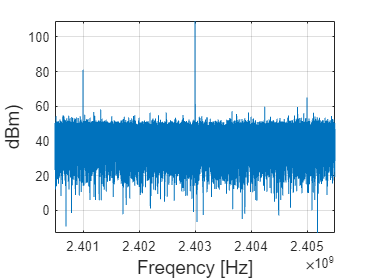

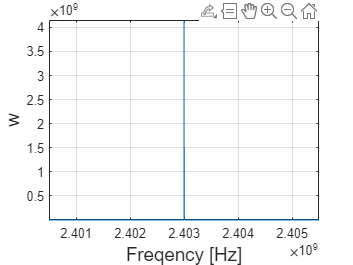

segmentDuration = 5;    % Duration of the segment in seconds
N = segmentDuration * Fs;    % Number of samples in the segment
%timeSignal = y(1:N,:);    % Extract the segment of the signal
%IQData = (timeSignal(:,1)+1i*timeSignal(:,2));
Result_FFT=Precise_FFT_plot(y4,1,Fs*5,Fs,centerfreq);

averagePower=mean(Result_FFT)

averagePower = 4.2723e+04

## psd

T = 1/Fs; % Sample time 
L = N; % Length of signal 
t = (0:L-1)*T; % Time vector
x = IQData;

Unrecognized function or variable 'IQData'.

xdft = fft(x);
Pxx = 1/(L*Fs)*abs(xdft(1:length(x)/2+1)).^2;
freq = 0:Fs/L:Fs/2;
plot(freq,10*log10(Pxx));
xlabel('Hz'); ylabel('dB/Hz');

## spectrogram

windowSize=2^20 ;
window=hamming(windowSize);
overlap=windowSize/2;

[s, f, t] =spectrogram(IQData,window ,overlap, 4096,Fs,'centered', "yaxis","psd");
%spectrogram(timeSignal(:,1), windowSize, overlap, [], Fs,"yaxis","psd");
%[s, f, t] = spectrogram(timeSignal(:,1), windowSize, overlap, [], Fs,"psd");
spectrogram_dB = 10 * log10(abs(s));

figure;
%imagesc(t, f, spectrogram_dB);
imagesc(t, f+centerfreq, spectrogram_dB);
axis xy;  % Flip the y-axis to align with the conventional spectrogram orientation
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram');
colorbar;  % Add a color bar for the magnitude scale
colormap;
overallPower = sum(abs(s(:)).^2)  % Calculate the sum of squared magnitudes
averagepower=overallPower/length(abs(s(:)).^2)


% figure;
% imagesc(t, f_band, spectrogram_dB_band);
% axis xy;  % Flip the y-axis to align with the conventional spectrogram orientation
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% title('Spectrogram (Bandwidth: 5 MHz)');
% colorbar;  % Add a color bar for the magnitude scale
[s2, f2, t2]=spectrogram(timeSignal(:,1),window ,overlap, 4096,Fs, "yaxis","psd");
overallPower2 = sum(abs(s2(:)).^2)  % Calculate the sum of squared magnitudes